# Electromagnetic Analysis of Intelligent Reflecting Surface

load magreflection_vs_observation_angle.mat
% load magreflection_vs_incident_angle.mat

fontsize=15;

This example shows how to model the response of an intelligent reflecting surface (IRS) using full-wave electromagnetic simulation. The IRS, also known as the reconfigurable intelligent surface (RIS), large intelligent surface (LIS), or metasurface, has garnered significant interest in the wireless communication community. The IRS consists of a large array of subwavelength unit cell elements which can manipulate the phase, amplitude, polarization, or frequency of the incident signal. If an obstacle blocks the direct path between the base station (BS) and the user equipment (UE), the parasitic reflection of the IRS can provide an alternative path for signal transmission, as this figure shows. An external phase control mechanism can be integrated to control the reflection characteristics of the IRS.

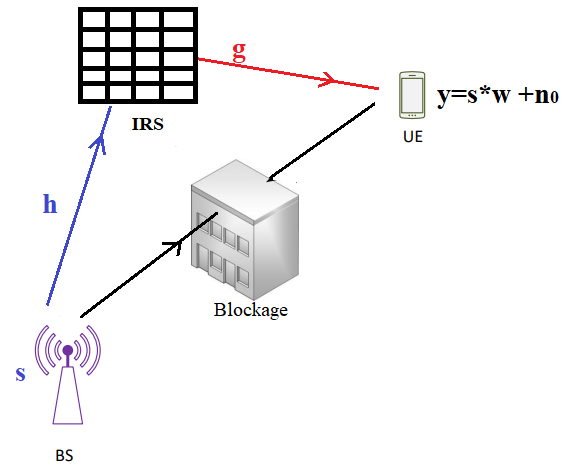

The inclusion of the RIS provides a two-segment indirect path to the signal traveling between the BS and the UE. The first segment covers the path between the BS and the IRS. The second segment covers the path between the IRS and the UE. The channel matrix of these two signal paths depends on the geometry and the electromagnetic reflection properties of the IRS.

The signal received at the UE is represented mathematically in [1] using this equation.

$r=sw+n_0=s\frac{\sqrt{G_rG_uG_tA_rA_u}}{4\pi}\sum_{n=1}^N \frac{\sqrt{\tilde{F}_n}R}{d_{tn}d_{rn}}e^\frac{-j2\pi(d_{tn}+d_{rn})}{\lambda}+n_0$,

where

- 
$$R=[R_1~R_2~......R_n]^T.$$


- $G_u$ is the embedded gain of the $n^{th}$ IRS element.

- $G_t$ is the embedded gain of the BS transmitter.

- $G_r$ is the embedded gain of the UE receiver.

- $F_n=F_n^tF_n^rF_{n}^{tx}F^{rx}_n$ is the product of the normalized power patterns of the BS, UE, and IRS.

- $d_t$ is the distance between the BS and the $n^{th}$ IRS element.

- $d_r$ is the distance between the UE and the $n^{th}$ IRS element.

- $A_r$ is the  effective aperture area of the UE.

- $A_u$ is the effective aperture area of the $n^{th}$ IRS element.

- $\lambda$ is the free-space wavelength.

For this example, assume that the IRS has $$N$$ unit cell elements. The complex reflection coefficient of the $n^{th}$ IRS element is denoted by $R_n=R^{mag}_n e^{j\tau_n}$.

The reflection coefficients of the IRS depend on these factors:

- Direction and polarization of the incoming signal towards the IRS.

- Direction and polarization of the outgoing signal from the IRS.

- Material properties and geometry of the IRS.

This example focuses on varying the incident signal configurations and determining the corresponding reflection characteristics.

Assume that $d_{tn}$ and $d_{rn}$ are in the far-field range. You can abstract the IRS as [infiniteArray](docid:antenna_ref#bvfg_q0-1) catalog element with a [planeWaveExcitation](docid:antenna_ref#bvj2_xq-1) model.

## Create and Visualize Geometry of Unit Cell

Design a reflector-backed dipole antenna at the operation frequency `F0` using the [reflector](docid:antenna_ref#bvclvwc-1) and [dipole](docid:antenna_ref#bvbbmax-1) objects. Tilt the dipole to make it horizontal to the ground plane. Visualize the reflector element using the `show` function. The ground plane length and reflector width determine the periodicity of the IRS.

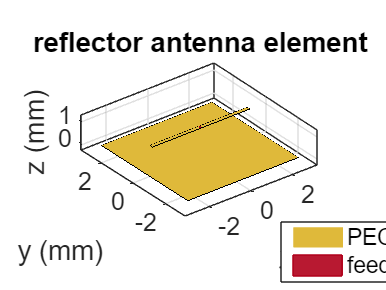

rf = design(reflector,F0);
rf.Spacing = lambda/10;
rf.GroundPlaneLength = 0.5*lambda;
rf.GroundPlaneWidth = 0.5*lambda;
figure;
show(rf);
xlabel('$x$ [mm]','FontSize',fontsize,'Interpreter','latex');
xlabel('$y$ [mm]','FontSize',fontsize,'Interpreter','latex');
set(gca,'FontSize',fontsize);

## Create and Visualize the Infinite IRS

Commonly, IRS configurations contain a very large number of array elements. Considering the long simulation time of such a large array, infinite array approximation using a periodic Green's function is a suitable alternative. In the [Modelling Mutual Coupling in Large Arrays Using Infinite Array Analysis](docid:antenna_ug#example-ex37130374) example, you design the IRS using an `infiniteArray` object.

Assign the reflector as the unit cell element of the IRS. Specify the scan angles of the IRS based on the receiver direction. The accuracy of infinite array modeling depends on the number of summation terms in the periodic Green's function, which you can se using `numSummationTerms`. Use the `show` function to visualize the IRS.

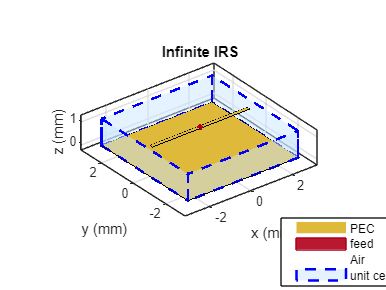

irs = infiniteArray(Element=rf);
% irs.ScanAzimuth = phi_obs;
% irs.ScanElevation = elevation_obs;
numSummationTerms(irs,20);
figure;
show(irs)
title("Infinite IRS")

%Compute the Array factor
AF=hArrayFactorCalc(irs,F0);

#### Depicting the Scenario

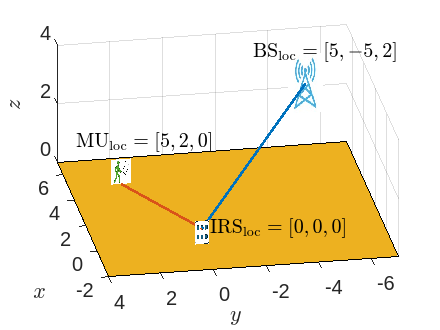

figure;
%depicting the MU
rot_az=100*2*pi/360;
rx_size=1.7;
img = imread('figures/MU.jpg');
[row,col]=size(img);
xImage = [pos_rx(1) pos_rx(1);...
          pos_rx(1) pos_rx(1)]; % The x data for the image corners
yImage = [pos_rx(2)-row/col*rx_size*sin(rot_az) pos_rx(2)+row/col*rx_size*sin(rot_az);...
          pos_rx(2)-row/col*rx_size*sin(rot_az) pos_rx(2)+row/col*rx_size*sin(rot_az)]; % The y data for the image corners

zImage = [pos_rx(3)+rx_size/2 pos_rx(3)+rx_size/2;...
          pos_rx(3) pos_rx(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none'); hold on;
txt=strcat("$$\mathrm{MU}_\mathrm{loc}=[",num2str(pos_rx(1)),",",num2str(pos_rx(2)),",",num2str(pos_rx(3)),"]$");
text(pos_rx(1),pos_rx(2)+rx_size,pos_rx(3)+0.9*rx_size,txt,'Interpreter','latex','FontSize',fontsize);

%depicting the BS
rot_az=0*2*pi/360;
% rot_el=30*2*pi/360;
tx_size=2;
img = imread('figures/BS.jpg');
[row,col]=size(img);
xImage = [pos_tx(1) pos_tx(1);...
          pos_tx(1) pos_tx(1)]; % The x data for the image corners
yImage = [pos_tx(2)-row/col*tx_size*cos(rot_az) pos_tx(2)+row/col*tx_size*cos(rot_az);...
          pos_tx(2)-row/col*tx_size*cos(rot_az) pos_tx(2)+row/col*tx_size*cos(rot_az)]; % The y data for the image corners

zImage = [pos_tx(3)+tx_size pos_tx(3)+tx_size;...
          pos_tx(3) pos_tx(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{BS}_\mathrm{loc}=[",num2str(pos_tx(1)),",",num2str(pos_tx(2)),",",num2str(pos_tx(3)),"]$");
text(pos_tx(1),pos_tx(2)+tx_size,pos_tx(3)+1.1*tx_size,txt,'Interpreter','latex','FontSize',fontsize);

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
set(gca,'FontSize',fontsize);

%depicting the IRS
IRS_size=D_h*N_v*2;
img = imread('figures/IRS.jpg');
xImage = [pos_IRS(2) pos_IRS(2);...
          pos_IRS(2) pos_IRS(2)]; % The X data for the image corners

yImage = [pos_IRS(1)+IRS_size pos_IRS(1)-IRS_size;...
          pos_IRS(1)+IRS_size pos_IRS(1)-IRS_size]; % The Y data for the image corners


zImage = [pos_IRS(3)+col/row*IRS_size pos_IRS(3)+col/row*IRS_size;...
          pos_IRS(3) pos_IRS(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{IRS}_\mathrm{loc}=[",num2str(pos_IRS(1)),",",num2str(pos_IRS(2)),",",num2str(pos_IRS(3)),"]$");
text(pos_IRS(1)+IRS_size,pos_IRS(2)-1.3*IRS_size,pos_IRS(3)+0.5*IRS_size*col/row,txt,'Interpreter','latex','FontSize',fontsize);

%depicting the line from the BS to the IRS
plot3([pos_tx(1) pos_IRS(1)],[pos_tx(2) pos_IRS(2)], [pos_tx(3)+tx_size/2 pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the line from the IRS to the MU
plot3([pos_rx(1) pos_IRS(1)],[pos_rx(2) pos_IRS(2)], [pos_rx(3) pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the ground plane
rect=rectangle('Position',[min([pos_tx(1),pos_IRS(1),pos_rx(1)])-max([tx_size,IRS_size,rx_size])...
                           min([pos_tx(2),pos_IRS(2),pos_rx(2)])-max([tx_size,IRS_size,rx_size]) ...
                           max([pos_tx(1),pos_IRS(1),pos_rx(1)])-min([pos_tx(1),pos_IRS(1),pos_rx(1)])+2*max([tx_size,IRS_size,rx_size]) ...
                           max([pos_tx(2),pos_IRS(2),pos_rx(2)])-min([pos_tx(2),pos_IRS(2),pos_rx(2)])+2*max([tx_size,IRS_size,rx_size]) ...
                           ],'FaceColor',"#EDB120");


axis([min([pos_tx(1),pos_IRS(1),pos_rx(1)])-max([tx_size,IRS_size,rx_size]) ...
      max([pos_tx(1),pos_IRS(1),pos_rx(1)])+max([tx_size,IRS_size,rx_size])...
      min([pos_tx(2),pos_IRS(2),pos_rx(2)])-max([tx_size,IRS_size,rx_size]) ...
      max([pos_tx(2),pos_IRS(2),pos_rx(2)])+max([tx_size,IRS_size,rx_size])...
      min([pos_tx(3),pos_IRS(3),pos_rx(3)]) ...
      max([pos_tx(3),pos_IRS(3),pos_rx(3)])+max([tx_size,IRS_size,rx_size])]);

view([-82.14 48.06])
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
set(gca,'FontSize',fontsize);

view([-100 45])

## Visualize Reflection Characterstics

Visualize the magnitude and phase of the reflection coefficients. Both the parameters depend on the polarization of incident and reflected signals. Based on the phase of the reflection coefficients, the signal at the receiver end can be constructively or destructively interfered to enhance or reduce the received signal strength, respectively, in a specific observation direction.

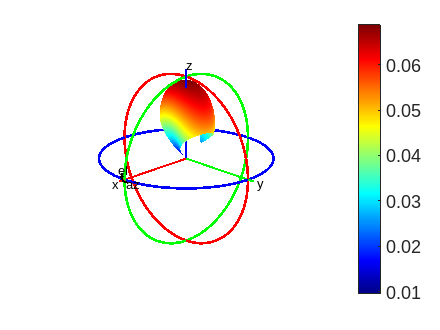

% figure;
% plot(theta_inc,MagReflection(5,:),"b")
% title("Reflection Coefficient Magnitude Against Incidence Angle")
% xlabel("Incidence Angle (\theta_{inc} in degree)")
% ylabel("Field Reflection Coefficient")
% 
% figure;
% plot(theta_inc,PhaseReflection(5,:),"b")
% title("Reflection Coefficient Phase Against Incidence Angle")
% xlabel("Incidence angle (\theta_{inc} in degree)")
% ylabel("Field Reflection Coefficient Phase")

figure;
hplot=patternCustom(MagReflection(:,1),MagReflection(:,2),MagReflection(:,3));

xlabel('$z$','Interpreter','latex');
zlabel('$x$','Interpreter','latex');
set(gca,'FontSize',fontsize)

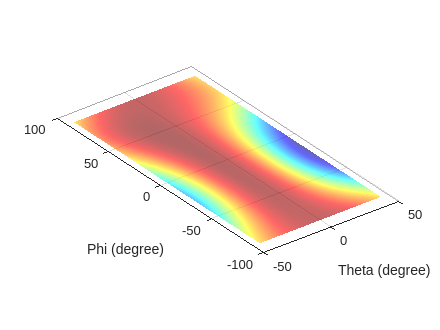


figure;
p = PatternPlotOptions(Transparency=0.6);
patternCustom(MagReflection(:,1),MagReflection(:,2),MagReflection(:,3),...
 CoordinateSystem="rectangular", PatternOptions=p);

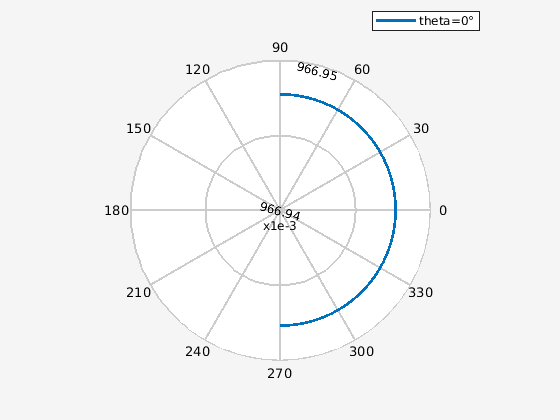

figure;
theta=hplot.YData(1,:);
phi=hplot.XData(:,1);
hplot_polar=patternCustom(hplot.ZData, theta*180/pi, -90:1:90, CoordinateSystem="polar",...
    Slice="theta", SliceValue=0);

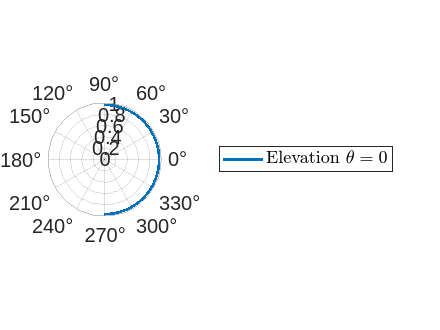

figure;
%pattern(hplot_polar.MagnitudeData,1,0,hplot_polar);
polarplot(hplot_polar.AngleData*pi/180,hplot_polar.MagnitudeData,'LineWidth',2);
legend('Elevation $\theta=0$','Interpreter','latex');
set(gca,'FontSize',fontsize);

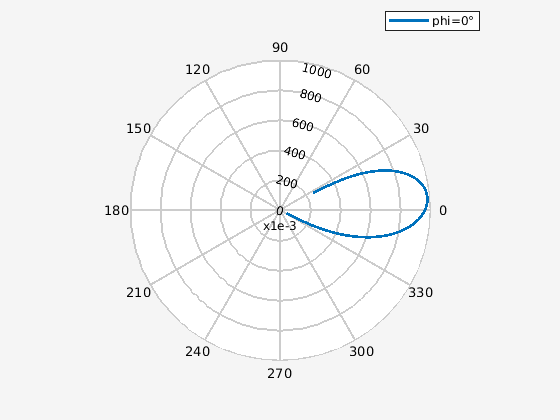

figure;
theta=hplot.YData(1,:);
phi=hplot.XData(1,:);
hplot_polar=patternCustom(hplot.ZData, theta*180/pi, -90:1:90, CoordinateSystem="polar",...
    Slice="phi", SliceValue=0);

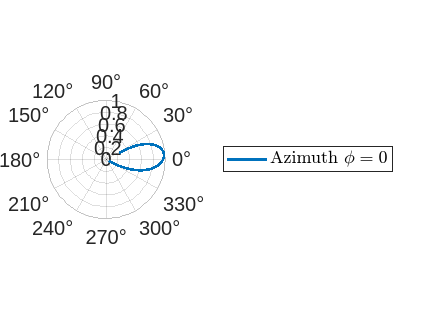

figure;
%pattern(hplot_polar.MagnitudeData,1,0,hplot_polar);
polarplot(hplot_polar.AngleData*pi/180,hplot_polar.MagnitudeData,'LineWidth',2);
legend('Azimuth $\phi=0$','Interpreter','latex');
set(gca,'FontSize',fontsize);

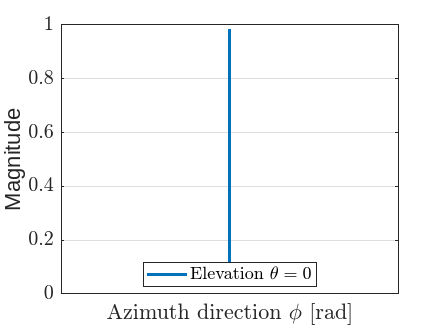


figure
theta=hplot.YData(:,1);
phi=hplot.XData(1,:);
patternCustom(hplot.ZData', theta, phi, CoordinateSystem="rectangular",...
    Slice="theta", SliceValue=0);
xlabel('Azimuth direction $\phi$ [rad]','Interpreter','latex');
legend('Elevation $\theta=0$','Interpreter','latex');

set(gca, 'XTick', [-45:10:20]);
x_ticks=cell(1,3);
for m=1:3
  x_ticks{m}=strcat("$t=",num2str((m-1)*10),"$");
end
 
set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

set(gca,'FontSize',fontsize);

You can do this analysis by using alternate infinite array configurations and different unit cell element to achieve desired IRS channel matrix behavior. Based on the phase of the reflection coefficients, the signal at the receiver's end can be constructively/destructively interfered to enhance/reduce the received signal strength in a specific observation direction.

## Further Exploration

Using the full-wave electromagnetic solution of Maxwell's equations from Antenna Toolbox™, you can perform a similar analysis with different IRS configurations constructed from the `infiniteArray` and `planeWaveExcitation` objects to design a physics-based smart propagation environment. The geometry of an IRS can be further integrated with Communication Toolbox™ and Optimization Toolbox™ software to obtain an accurate, physics-based characterization of IRS-aided wireless communication scenarios.

## Reference

[1] Cui, Yaoshen, Haifan Yin, Li Tan, and Marco Di Renzo., " A 3D Positioning-based Channel Estimation Method for RIS-aided mmWave Communications." arXiv:2203.14636 (April 21, 2022). [https://doi.org/10.48550/arXiv.2203.14636](https://doi.org/10.48550/arXiv.2203.14636).

*Copyright 2022 The MathWorks, Inc.*